#     1.

close all; clear all;

## a)

I = [-2 0 0 2; -.5 -4 0 -1.5; -1 -4 -1.5 -1; .5 -2 -.5 -1.5];
V = diag([2 1 4 2]);

A = I * V

A =     -4     0     0     4
    -1    -4     0    -3
    -2    -4    -6    -2
     1    -2    -2    -3


Estudio de la estabilidad de los precios

[vA, lA] = eig(A)

vA =     0.5774   -0.2440    0.5643    0.8729
   -0.5774    0.6175   -0.2648   -0.2182
   -0.0000   -0.7470   -0.5991    0.0000
    0.5774   -0.0343   -0.5025   -0.4364


lA =    -0.0000         0         0         0
         0   -3.4384         0         0
         0         0   -7.5616         0
         0         0         0   -6.0000


Mirando los autovalores y autovectores, se puede observar que al final de la sesión E3 se irá a 0, y E1 y E4 irán al mismo valor. E2 irá al valor opuesto de E1 y E4.

## b) 

x0 = [10 1 3 0]

x0 =     10     1     3     0


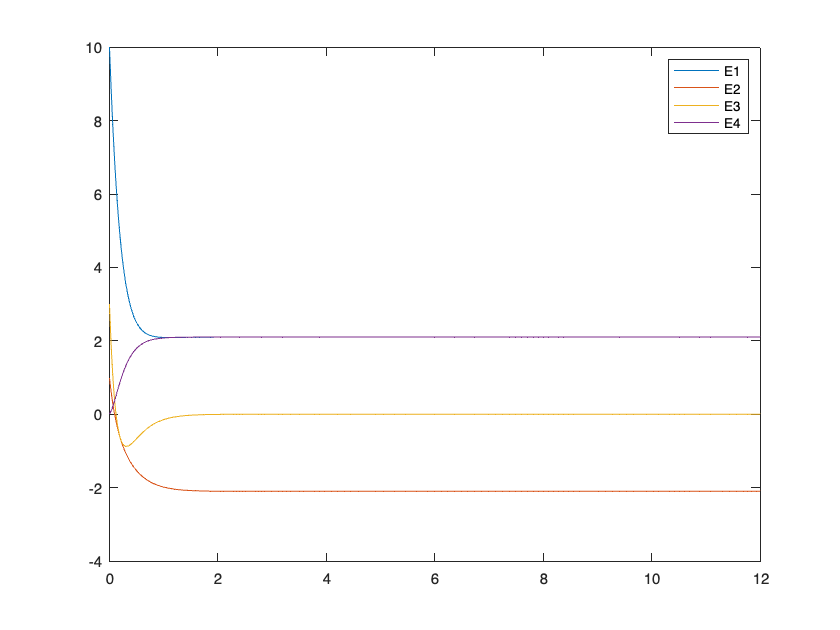

[t, x] = ode45(@(t, x) A * x, [0 12], x0');
figure(1)
plot(t,x)
legend("E1", "E2", "E3", "E4");

Se ve inmediatamente que E1 y E4 van al mismo valor (casi 2). E2 va a -2 y E3 se estabiliza en 0.

## c)

Vamos con el teorema 4.2.4 (test de autovectores)

[vAt, lAt] = eig(A')

vAt =     0.3946   -0.3618    0.6667   -0.3890
   -0.1435   -0.7236    0.6667   -0.7779
   -0.2870   -0.4634    0.3333    0.3037
    0.8610   -0.3618    0.0000   -0.3890


lAt =     0.0000         0         0         0
         0   -7.5616         0         0
         0         0   -6.0000         0
         0         0         0   -3.4384


Directamente mirando la matriz de autovectores de A traspuesta se ve que no se puede controlar el sistema solo invirtiendo en E4 (u = [0; 0; 0; 1]), porque el tercer autovector pertenecería al kernel.

[0 0 0 1]*vAt

ans =     0.8610   -0.3618    0.0000   -0.3890


Se ve que el resultado del tercer autovector no es controlable. Si yo además construyo la matriz de controlabilidad tal que

B = [0 0 0 1]';
Con = [B A*B A^2*B A^3*B]

Con =      0     4   -28   204
     0    -3    17  -109
     0    -2    22  -190
     1    -3    23  -175


rank(Con)

ans = 3

El rango de C no es 4, luego el sistema no es controlable.

Para cualquier otra B

B = [0 0 1 0]';
Con = [B A*B A^2*B A^3*B]

Con =      0     0    -8   104
     0     0     6   -70
     1    -6    40  -284
     0    -2    18  -154


rank(Con)

ans = 4

Se ve que el rango de la matriz de controlabilidad sí es 4.

## d)

Se puede hacer un test de autovectores. Recordando los autovectores de A

vA

vA =     0.5774   -0.2440    0.5643    0.8729
   -0.5774    0.6175   -0.2648   -0.2182
   -0.0000   -0.7470   -0.5991    0.0000
    0.5774   -0.0343   -0.5025   -0.4364


Se puede ver ya que el primer y cuatro autovector estarán en el kernel de C si la empresa 3 es la que facilita la información fiable. Esto se puede comprobar también estudiando el rango de la matriz de observabilidad.

C = [0 0 1 0];
Obs = [C; C*A; C*A^2; C*A^3]

Obs =      0     0     1     0
    -2    -4    -6    -2
    22    44    40    22
  -190  -380  -284  -190


rank(Obs)

ans = 2

El rango es 2, luego el sistema no es observable. Cambiando la empresa el rango sí es 4.

## e)

Vamos a invertir en una empresa controlable y observable, es decir, o la empresa 1 o la empresa 2. Vamos con la 2.

B = [0; 1; 0; 0];
C = [0 1 0 0];
x1 = [-10; 10; -10; -10]

x1 =    -10
    10
   -10
   -10


%Integrar para sacar el gramiano.
Wr = integral(@(t)dgramr(t, 6, A, B),0, 6, "ArrayValued", 1)

Wr =     0.0626   -0.0760    0.0128    0.0639
   -0.0760    0.2109   -0.0581   -0.0910
    0.0128   -0.0581    0.0280    0.0194
    0.0639   -0.0910    0.0194    0.0673


%Importante poner ArrayValued porque si no no tira la integral.
eta1 = Wr\x1

eta1 = 1.0e+03 *

   -4.4819
   -0.0553
   -1.5160
    4.4720


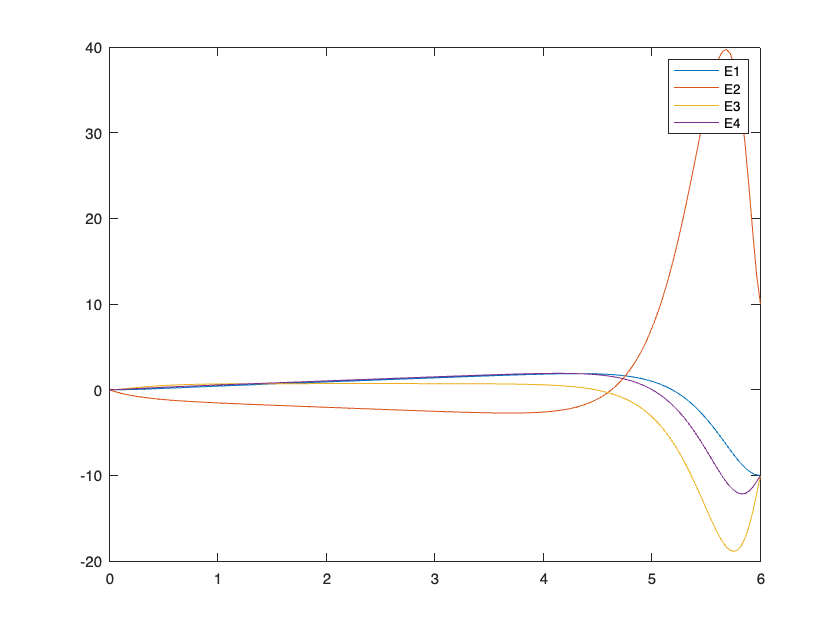

u = @(t) B'*expm(A'*(6 - t))*eta1; %u(t)

%El nuevo sistema es xdot(t) = Ax(t) + Bu(t)
[t, x] = ode45(@(t, x) A * x + B * u(t), [0 6], [0,0,0,0]');
figure(2)
plot(t, x)
legend("E1", "E2", "E3", "E4");

xf = x(end, :)

xf =   -10.0004   10.0016   -9.9971   -9.9986


## f)

Vamos a diseñar un controlador por realimentación de estados estimados.

K = acker(A, B, [-1, -2, -3, -4]);
L = acker(A', C', [-5, -6, -7, -8])'; 
%Queremos que el estimador converja al sistema antes de que el sistema
%converja a los valores de estabilización, luego los polos deben ser más
%negativos.

Aamp = [A, -B*K; L*C, A-B*K-L*C]

Aamp =    -4.0000         0         0    4.0000         0         0         0         0
   -1.0000   -4.0000         0   -3.0000    1.5000    7.0000    5.0000    7.0000
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0
         0  -10.1053         0         0   -4.0000   10.1053         0    4.0000
         0    9.0000         0         0    0.5000   -6.0000    5.0000    4.0000
         0    2.2105         0         0   -2.0000   -6.2105   -6.0000   -2.0000
         0  -10.6316         0         0    1.0000    8.6316   -2.0000   -3.0000


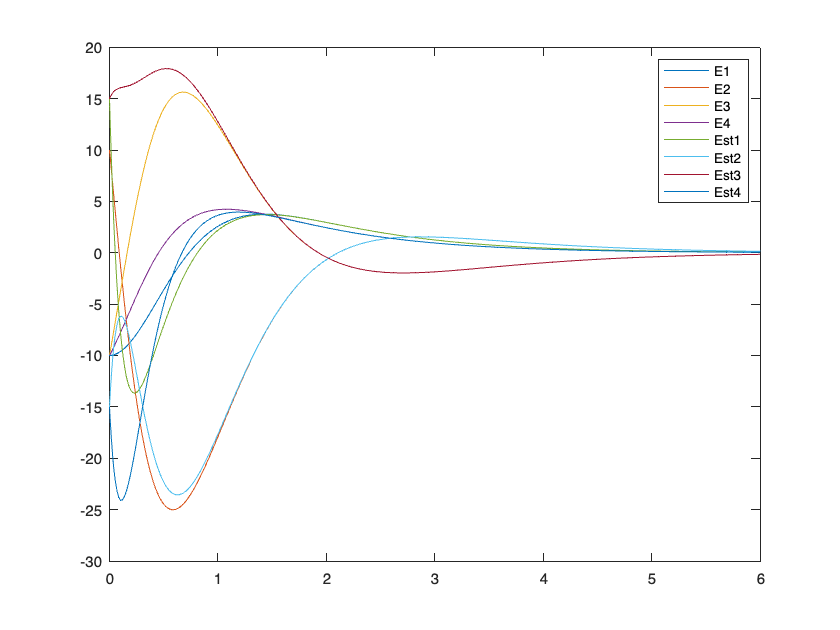

%Iniciamos el estimador donde nos dé la gana, por ejemplo [15 -15 15 -15].
x0amp = [xf, 15 -15 15 -15];
[t, xamp] = ode45(@(t, xamp) Aamp * xamp, [0 6], x0amp');
figure(3)
plot(t, xamp)
legend("E1", "E2", "E3", "E4", "Est1", "Est2", "Est3", "Est4");

## g)

Ahora hay que añadir control integral para que el resultado final tenga x2 = 15.

%El sistema ahora es de la forma 
% (xdot; edot) = [A 0; C2 0] (x; e) + [B; 0]u + [0 -I]yd

Ai = [A, zeros(4, 1); C, 0];
Bi = [B; 0];
%Comprobar que el par es controlable
rank([Bi Ai*Bi Ai^2*Bi Ai^3*Bi Ai^4*Bi])

ans = 5

%Obtener K con place o acker
Kt = place(Ai, Bi, [-1 -2 -3 -4 -5])

Kt =     0.6875   -2.0000   -3.7500    1.7500    7.5000


%Y el sistema ampliado (variables-estimador-error) será
Ampi = [A  -B*Kt(1:4) -B*Kt(5);
         L*C A-B*Kt(1:4)-L*C -B*Kt(5);
         C zeros(1,4) 0]

Ampi =    -4.0000         0         0    4.0000         0         0         0         0         0
   -1.0000   -4.0000         0   -3.0000   -0.6875    2.0000    3.7500   -1.7500   -7.5000
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0         0
         0  -10.1053         0         0   -4.0000   10.1053         0    4.0000         0
         0    9.0000         0         0   -1.6875  -11.0000    3.7500   -4.7500   -7.5000
         0    2.2105         0         0   -2.0000   -6.2105   -6.0000   -2.0000         0
         0  -10.6316         0         0    1.0000    8.6316   -2.0000   -3.0000         0
         0    1.0000         0         0         0         0         0         0         0


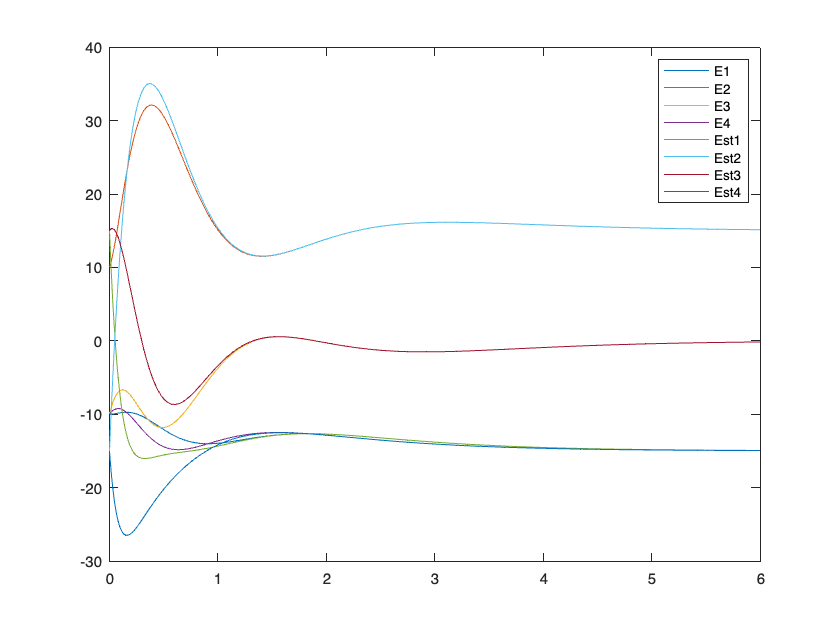

[t, xampi] = ode45(@(t, xampi) Ampi * xampi + [0 0 0 0 0 0 0 0 1]'*(-15), [0 6], [xf, 15 -15 15 -15, 0]); %El sistema es vdot = Ampi * vdot + W * -yd. 

figure(4)
plot(t, xampi(:,1:8))
legend("E1", "E2", "E3", "E4", "Est1", "Est2", "Est3", "Est4");

Ahora lo voy a repetir para la empresa 1

B1 = [1; 0; 0; 0];
C1 = [1 0 0 0];

%Ai es A añadiendo el error de la salida
%El sistema no debe actuar directamente sobre el error de la salida y C
%será lo que permita medir el error. La entrada tampoco actúa sobre el
%error.

% A A A A 0           B
% A A A A 0           B
% A A A A 0     +     B  
% A A A A 0           B
% C C C C 0           0

Ai1 = [A zeros(4,1); C1 0];
Bi1 = [B1; 0];
%Ya podemos sacar la ganancia

Kt1 = place(Ai1, Bi1, [-1 -2 -3 -4 -5])

Kt1 =    -2.0000   -7.7727   -5.3864   -2.2727    2.7273


%Y el sistema ampliado


$$\pmatrix{\dot{x}\cr \dot{\hat{x}}\cr \dot{e}}A_{mpo} =\pmatrix{A & -BK &-BK_i\cr LC& A-BK-LC\ & -BK_i &\cr C &0 &0}\pmatrix{x\cr \hat{x}\cr e}+ \pmatrix{0\cr 0\cr -yd} $$


L1 = place(A',C1',[-5,-6,-7,-8])';
Ampi1 = [A, - B1 * Kt1(1:4),  - B1 * Kt1(5); L1 * C1, A - B1 * Kt1(1:4) - L1 * C1, -B1 * Kt1(5); C1 zeros(1,4) 0]

Ampi1 =    -4.0000         0         0    4.0000    2.0000    7.7727    5.3864    2.2727   -2.7273
   -1.0000   -4.0000         0   -3.0000         0         0         0         0         0
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0         0
    9.0000         0         0         0  -11.0000    7.7727    5.3864    6.2727   -2.7273
   -6.2500         0         0         0    5.2500   -4.0000         0   -3.0000         0
   -5.5000         0         0         0    3.5000   -4.0000   -6.0000   -2.0000         0
   10.5000         0         0         0   -9.5000   -2.0000   -2.0000   -3.0000         0
    1.0000         0         0         0         0         0         0         0         0


yd1 = 15

yd1 = 15

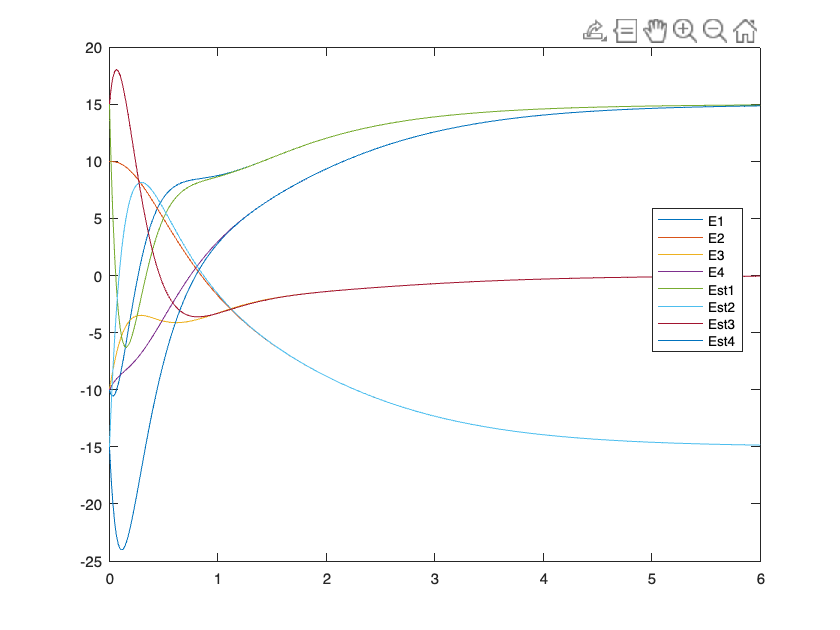

bmpo = [zeros(8, 1); 1];
[t, xampi1] = ode45(@(t, xampi1) Ampi1 * xampi1 - bmpo * yd1, [0 6], [xf, 15 -15 15 -15, 0]);
figure(5)
plot(t, xampi1(:,1:8))
legend("E1", "E2", "E3", "E4", "Est1", "Est2", "Est3", "Est4");

function dwr = dgramr(t, t0, A, B)
    %x(t) = phi(t, t0)x0 -> En este caso se ve que phi es exp(A(t - t0)), al
    %ser el sistema lineal.
    dwr = expm(A*(t0 - t)) * (B * B') * expm(A'*(t0 - t));
end